## Initialize

edit Start.mlx

## Set up Environment

rrAppPath = "C:\Program Files\RoadRunner R2022b\bin\win64";
rrProjectPath = fullfile(pwd, 'RoadRunner');
s = settings;
s.roadrunner.application.InstallationFolder.TemporaryValue = rrAppPath;

## Open RoadRunner

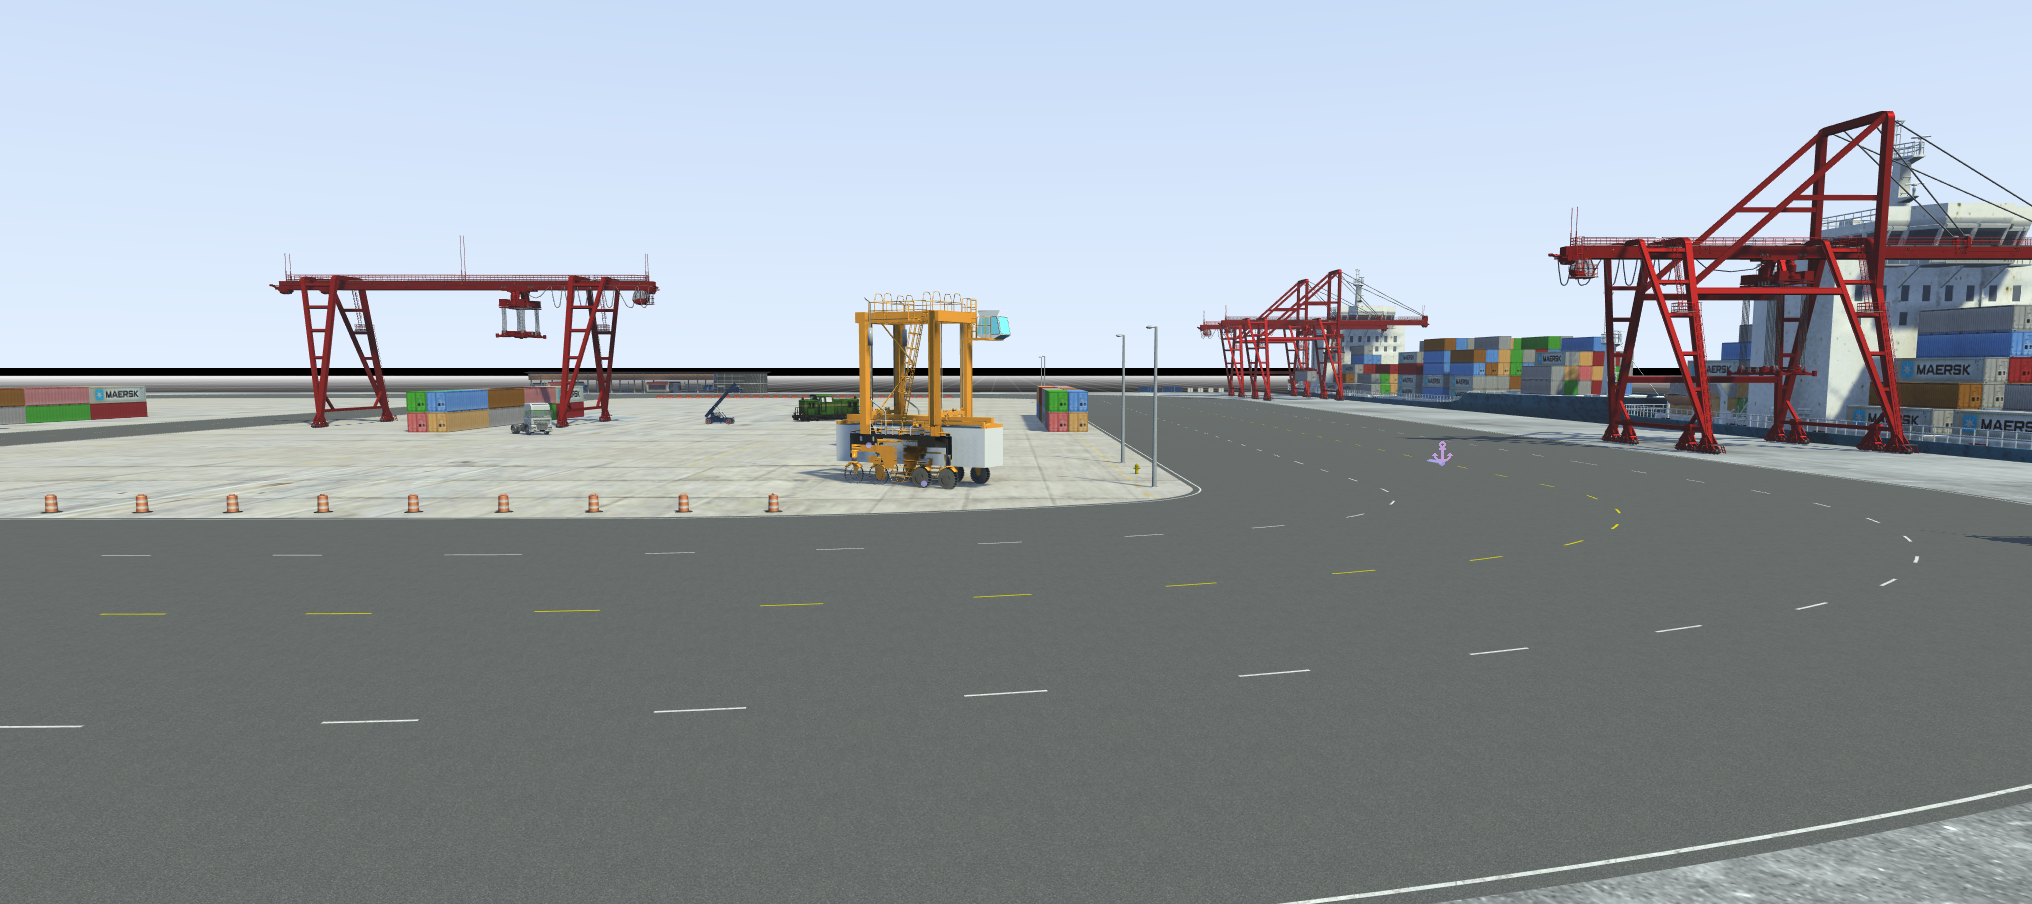

rrApp = roadrunner(rrProjectPath);
openScene(rrApp, "Port.rrscene")
openScenario(rrApp, "StraddleCarrier.rrscenario")
rrSim = rrApp.createSimulation;

Error using roadrunner/createSimulation
MATLAB is
connected with
RoadRunner
scenario
co-simulation
server at address:
'localhost:39093'.
MATLAB is limited
to connecting with
one RoadRunner
scenario
co-simulation
server.

set(rrSim, Logging = "on")
Ts = 0.05;
set(rrSim, StepSize = Ts) 

## Open Simulink

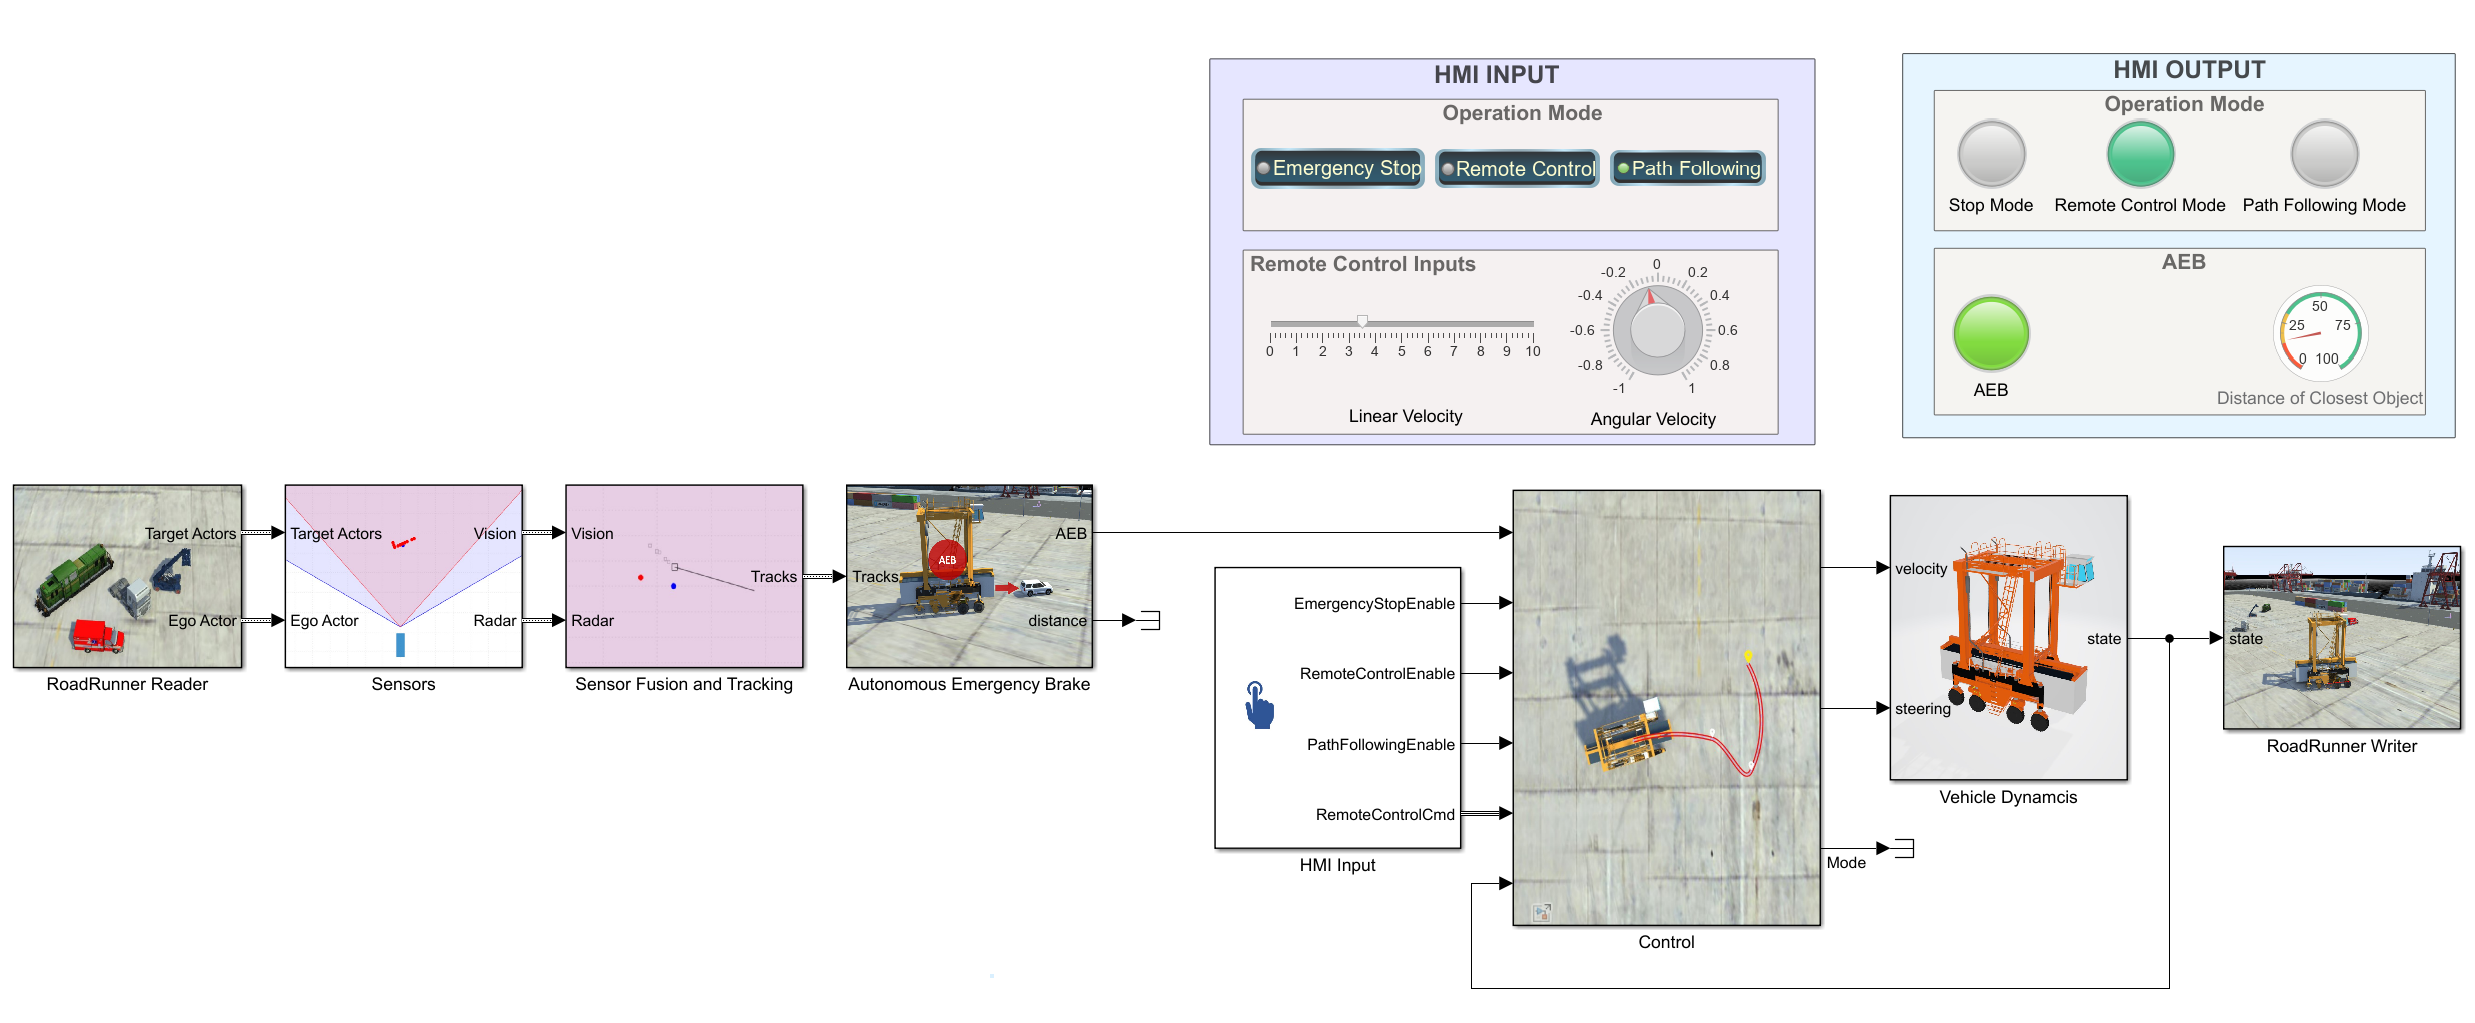

helperInitializeSimulink;
modelName = "StraddleCarrier";
open_system(modelName);

## Generate Trajectory for Path Following

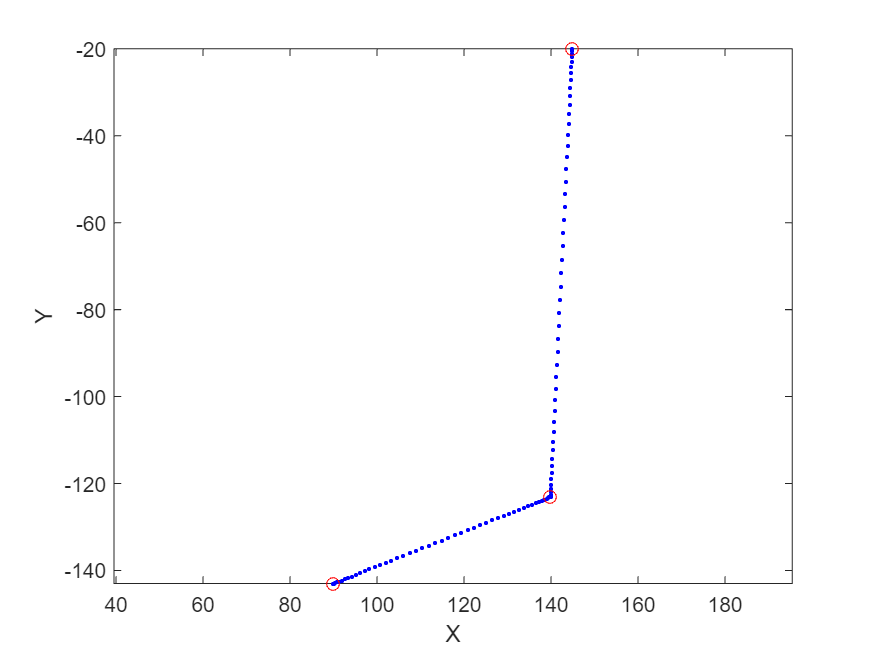

ComputeQuinticTrajectory

## Simulate

% set(rrSim, SimulationCommand = "Start")
% while strcmp(rrSim.get("SimulationStatus"), "Running")
%     pause(1)
% end